clear
load('./traces_v4/input_sets_second_op_31.mat');

%Settings for the dataset
numberOfSets = 1000;
setSize = 31;
totalComparisons = numberOfSets * (numberOfSets-1) / 2;
category = cell(1,totalComparisons);
val = zeros(1,totalComparisons);
inputComparison = inputs_b(1:31:size(inputs_b,1),:);
freq = 100e6;
samplesPerSec = 40e9;
samplesPerCycle = samplesPerSec/freq;
compressTraceSize = ceil(size(traces_Y,2)/samplesPerCycle);
clockIndexes = getClockIndexes();

meanTraces = getMeanTraces(traces_Y,numberOfSets,setSize);

## **Correlation**

%Test 1.1
index = 0;
for i = 1 : size(meanTraces,1) - 1
    for j = i + 1 : size(meanTraces,1)
        corrMat = corrcoef(meanTraces(i,:),meanTraces(j,:));
        index = index + 1;
        val(index) = corrMat(1,2);
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

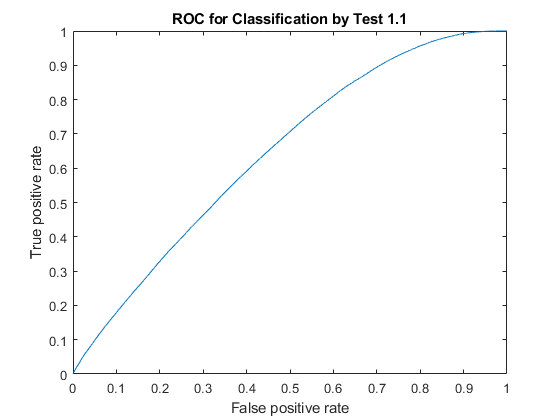

[X11,Y11,T11,AUC11,OPTROCPT11] = perfcurve(category',val','same');
plot(X11,Y11)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 1.1')
hold off

%Test 1.2
category = cell(1,totalComparisons);
compressTraces = compressMaxWithoutSync(meanTraces,compressTraceSize,samplesPerCycle);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        corrMat = corrcoef(compressTraces(i,:),compressTraces(j,:));
        index = index + 1;
        val(index) = corrMat(1,2);
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

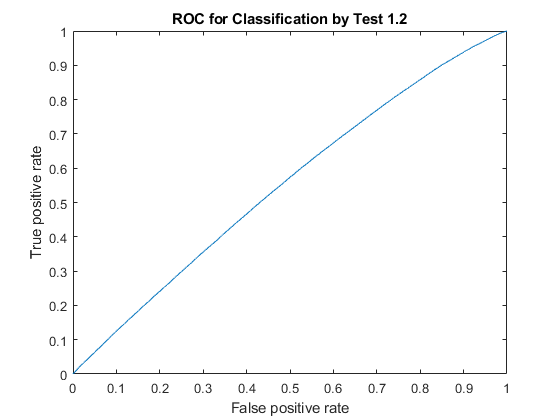

[X12,Y12,T12,AUC12,OPTROCPT12] = perfcurve(category',val','same');
plot(X12,Y12)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 1.2')
hold off

% Test 1.3
category = cell(1,totalComparisons);
compressTraces = compressAvgWithoutSync(meanTraces,compressTraceSize,samplesPerCycle);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        corrMat = corrcoef(compressTraces(i,:),compressTraces(j,:));
        index = index + 1;
        val(index) = corrMat(1,2);
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

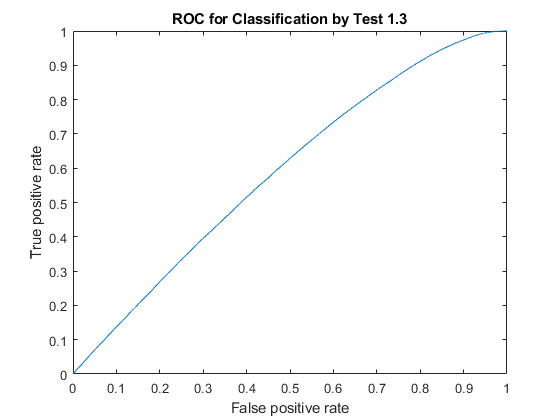

[X13,Y13,T13,AUC13,OPTROCPT13] = perfcurve(category',val','same');
plot(X13,Y13)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 1.3')
hold off

% Test 1.4 
category = cell(1,totalComparisons);
compressTraces = compressMaxWithoutSync(traces_Y,compressTraceSize,samplesPerCycle);
compressTraces = getMeanTraces(compressTraces,numberOfSets,setSize);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        corrMat = corrcoef(compressTraces(i,:),compressTraces(j,:));
        index = index + 1;
        val(index) = corrMat(1,2);
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

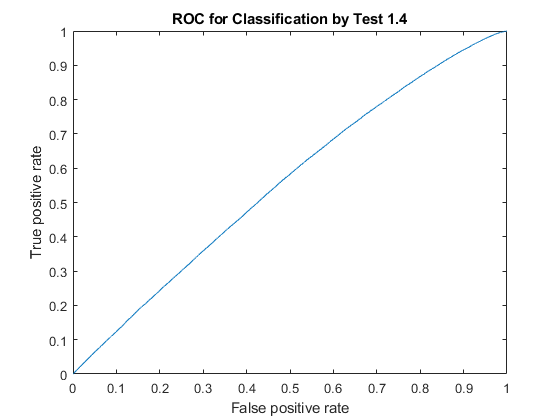

[X14,Y14,T14,AUC14,OPTROCPT14] = perfcurve(category',val','same');
plot(X14,Y14)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 1.4')
hold off

% Test 1.5 
category = cell(1,totalComparisons);
compressTraces = compressMaxWithSync(meanTraces,clockIndexes);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        corrMat = corrcoef(compressTraces(i,:),compressTraces(j,:));
        index = index + 1;
        val(index) = corrMat(1,2);
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

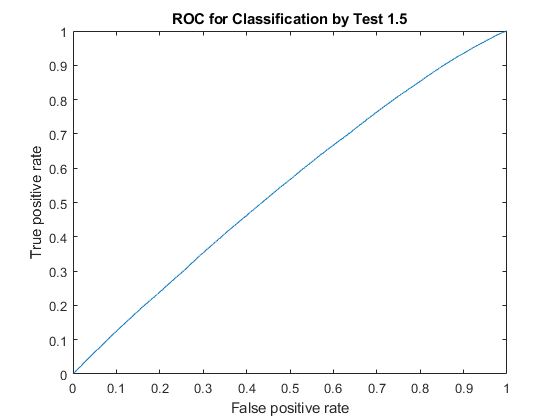

[X15,Y15,T15,AUC15,OPTROCPT15] = perfcurve(category',val','same');
plot(X15,Y15)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 1.5')
hold off

% Test 1.6 
category = cell(1,totalComparisons);
compressTraces = compressAvgWithSync(meanTraces,clockIndexes);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        corrMat = corrcoef(compressTraces(i,:),compressTraces(j,:));
        index = index + 1;
        val(index) = corrMat(1,2);
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

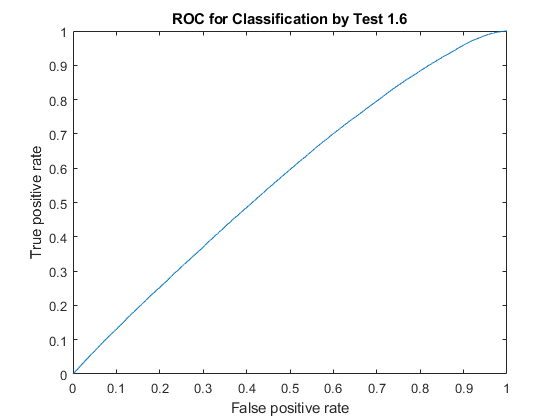

[X16,Y16,T16,AUC16,OPTROCPT16] = perfcurve(category',val','same');
plot(X16,Y16)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 1.6')
hold off

% Test 1.7
category = cell(1,totalComparisons);
compressTraces = compressMaxWithSync(traces_Y,clockIndexes);
compressTraces = getMeanTraces(compressTraces,numberOfSets,setSize);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        corrMat = corrcoef(compressTraces(i,:),compressTraces(j,:));
        index = index + 1;
        val(index) = corrMat(1,2);
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

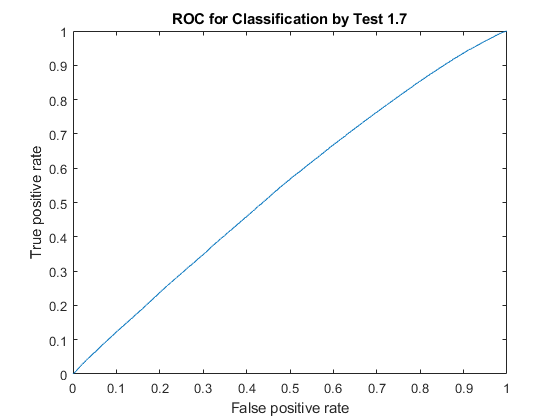

[X17,Y17,T17,AUC17,OPTROCPT17] = perfcurve(category',val','same');
plot(X17,Y17)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 1.7')
hold off

% Test 1.8
category = cell(1,totalComparisons);
compressTraces = compressSqrWithSync(traces_Y,clockIndexes);
compressTraces = getMeanTraces(compressTraces,numberOfSets,setSize);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        corrMat = corrcoef(compressTraces(i,:),compressTraces(j,:));
        index = index + 1;
        val(index) = corrMat(1,2);
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

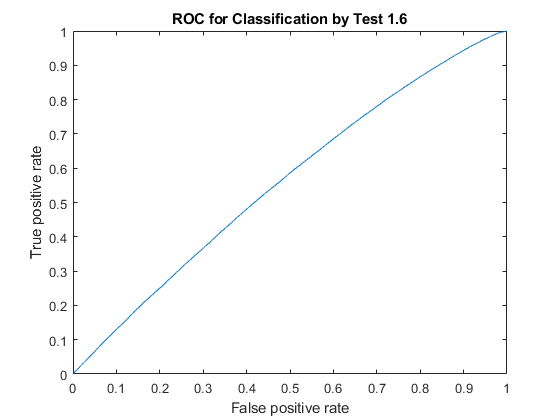

[X18,Y18,T18,AUC18,OPTROCPT18] = perfcurve(category',val','same');
plot(X18,Y18)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 1.6')
hold off

## **Euclidean distance**

%Test 2.1
category = cell(1,totalComparisons);
index = 0;
for i = 1 : size(meanTraces,1) - 1
    for j = i + 1 : size(meanTraces,1)
        index = index + 1;
        val(index) = norm(meanTraces(i,:) - meanTraces(j,:));
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

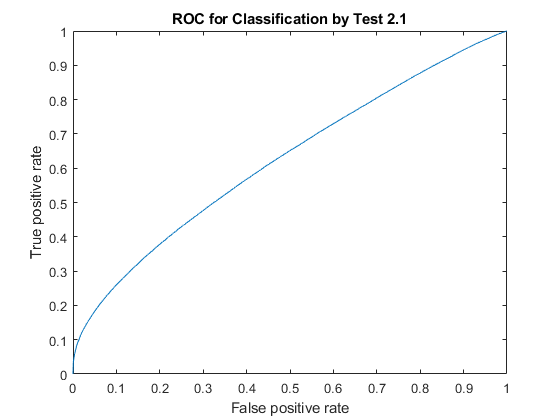

[X21,Y21,T21,AUC21,OPTROCPT21] = perfcurve(category',val','different');
plot(X21,Y21)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 2.1')
hold off

%Test 2.2
category = cell(1,totalComparisons);
compressTraces = compressMaxWithoutSync(meanTraces,compressTraceSize,samplesPerCycle);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        index = index + 1;
        val(index) = norm(compressTraces(i,:) - compressTraces(j,:));
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

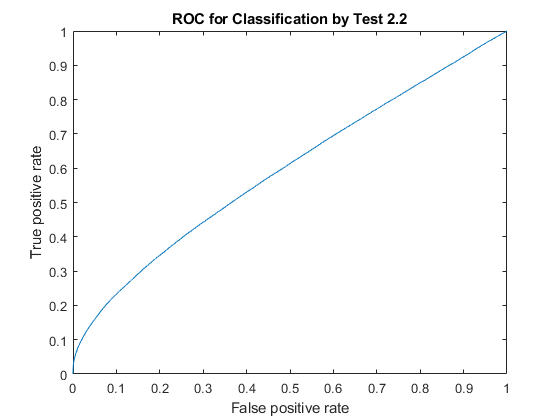

[X22,Y22,T22,AUC22,OPTROCPT22] = perfcurve(category',val','different');
plot(X22,Y22)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 2.2')
hold off

%Test 2.3
category = cell(1,totalComparisons);
compressTraces = compressAvgWithoutSync(meanTraces,compressTraceSize,samplesPerCycle);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        index = index + 1;
        val(index) = norm(compressTraces(i,:) - compressTraces(j,:));
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

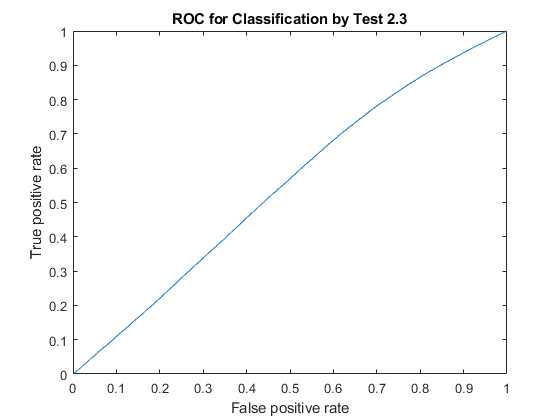

[X23,Y23,T23,AUC23,OPTROCPT23] = perfcurve(category',val','different');
plot(X23,Y23)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 2.3')
hold off

%Test 2.4
category = cell(1,totalComparisons);
compressTraces = compressMaxWithoutSync(traces_Y,compressTraceSize,samplesPerCycle);
compressTraces = getMeanTraces(compressTraces,numberOfSets,setSize);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        index = index + 1;
        val(index) = norm(compressTraces(i,:) - compressTraces(j,:));
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

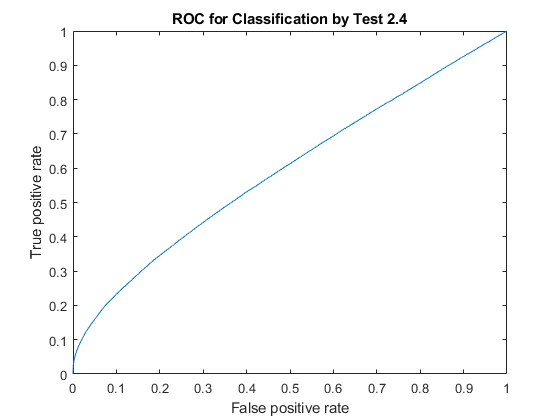

[X24,Y24,T24,AUC24,OPTROCPT24] = perfcurve(category',val','different');
plot(X24,Y24)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 2.4')
hold off

%Test 2.5
category = cell(1,totalComparisons);
compressTraces = compressMaxWithSync(meanTraces,clockIndexes);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        index = index + 1;
        val(index) = norm(compressTraces(i,:) - compressTraces(j,:));
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

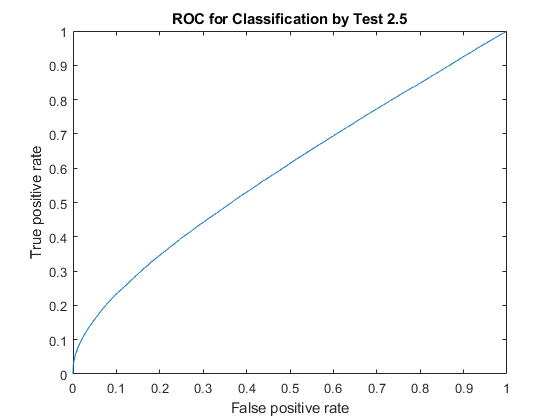

[X25,Y25,T25,AUC25,OPTROCPT25] = perfcurve(category',val','different');
plot(X25,Y25)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 2.5')
hold off

%Test 2.6
category = cell(1,totalComparisons);
compressTraces = compressAvgWithSync(meanTraces,clockIndexes);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        index = index + 1;
        val(index) = norm(compressTraces(i,:) - compressTraces(j,:));
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

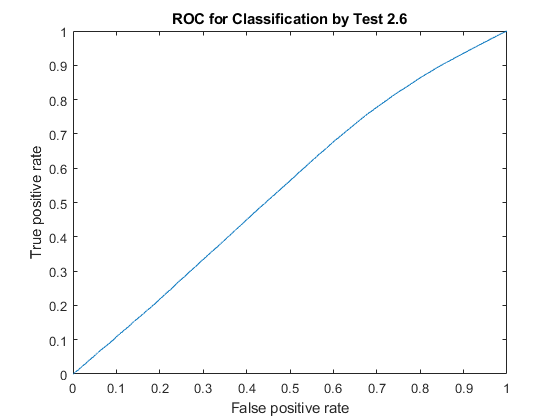

[X26,Y26,T26,AUC26,OPTROCPT26] = perfcurve(category',val','different');
plot(X26,Y26)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 2.6')
hold off

%Test 2.7
category = cell(1,totalComparisons);
compressTraces = compressMaxWithSync(traces_Y,clockIndexes);
compressTraces = getMeanTraces(compressTraces,numberOfSets,setSize);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        index = index + 1;
        val(index) = norm(compressTraces(i,:) - compressTraces(j,:));
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

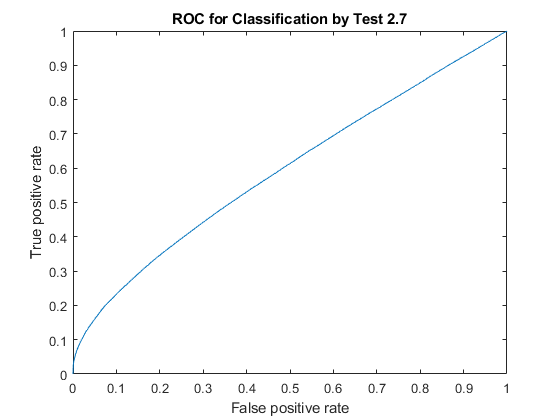

[X27,Y27,T27,AUC27,OPTROCPT27] = perfcurve(category',val','different');
plot(X27,Y27)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 2.7')
hold off

%Test 2.8
category = cell(1,totalComparisons);
compressTraces = compressSqrWithSync(traces_Y,clockIndexes);
compressTraces = getMeanTraces(compressTraces,numberOfSets,setSize);
index = 0;
for i = 1 : size(compressTraces,1) - 1
    for j = i + 1 : size(compressTraces,1)
        index = index + 1;
        val(index) = norm(compressTraces(i,:) - compressTraces(j,:));
        if (hammingWeight(hex2dec(inputComparison(i,:))) == hammingWeight(hex2dec(inputComparison(j,:))))
            category(index) = {'same'};
        else
            category(index) = {'different'};
        end
    end
end

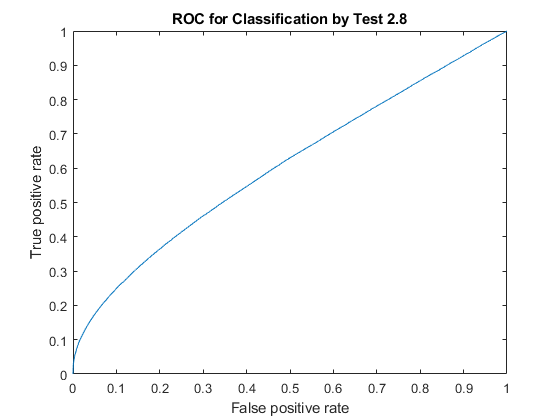

[X28,Y28,T28,AUC28,OPTROCPT28] = perfcurve(category',val','different');
plot(X28,Y28)
hold on
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for Classification by Test 2.8')
hold off

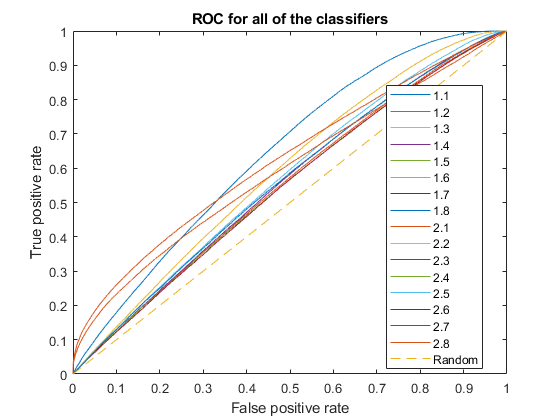

%Plot all of them 
plot(X11,Y11)
hold on
plot(X12,Y12)
plot(X13,Y13)
plot(X14,Y14)
plot(X15,Y15)
plot(X16,Y16)
plot(X17,Y17)
plot(X18,Y18)
plot(X21,Y21)
plot(X22,Y22)
plot(X22,Y22)
plot(X22,Y22)
plot(X22,Y22)
plot(X22,Y22)
plot(X22,Y22)
plot(X22,Y22)
plot(0:1,0:1,'--')
legend('1.1','1.2','1.3','1.4','1.5','1.6','1.7','1.8','2.1','2.2','2.3','2.4','2.5','2.6','2.7','2.8','Random','Location','Best')
xlabel('False positive rate') 
ylabel('True positive rate')
title('ROC for all of the classifiers')
hold off

AUC11

AUC11 = 0.6443

AUC12

AUC12 = 0.5509

AUC13

AUC13 = 0.5905

AUC14

AUC14 = 0.5567

AUC15

AUC15 = 0.5474

AUC16

AUC16 = 0.5687

AUC17

AUC17 = 0.5463

AUC18

AUC18 = 0.5599

AUC21

AUC21 = 0.6242

AUC22

AUC22 = 0.5947

AUC23

AUC23 = 0.5461

AUC24

AUC24 = 0.5946

AUC25

AUC25 = 0.5947

AUC26

AUC26 = 0.5430

AUC27

AUC27 = 0.5950

AUC28

AUC28 = 0.6066

cursor_info

Unrecognized function or variable 'cursor_info'.

T21(cursor_info.DataIndex)